Doppler - Matlab Implementation

settings 

freq_off = 3; %small offset 
txfilter = comm.RaisedCosineTransmitFilter(); %tx srrc
rxfilter = comm.RaisedCosineReceiveFilter(); %rx srrc
M = 16; %modulation order
nb = 10e4;  %10,000 integers 
LO = dsp.SineWave("Frequency", 1.5e9, "ComplexOutput", true, "SampleRate", (1e-6)/8, "SamplesPerFrame", 8*nb); 
y = LO(); %up conversion
pfo = comm.PhaseFrequencyOffset('FrequencyOffset', freq_off, 'SampleRate', 8/(1e-6));
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',5e3, 'ShowReferenceConstellation', 0, 'NumInputPorts', 2);


Generate data, apply cfo 

msg = randi([0 sum(M)-1], nb, 1);
symbols = dvbsapskmod(msg, M, 's2x'); 

txData = txfilter(symbols);
txData = txData.*y; 
rxData = pfo(txData); 
rxData = rxData.*conj(y); 
rxData = rxfilter(rxData); 

constDiagram(symbols(1:length(rxData)-10), rxData(11:end)); 

Matlab introduces cfo as a summation, the following introduces cfo as described in this video: [https://www.youtube.com/watch?v=d6F5HYeZfPE](https://www.youtube.com/watch?v=d6F5HYeZfPE)

ratio_1 = 5e-6; 
ratio_2 = 10e-6; 
ratio_3 = 1e-6; 
ratio_4 = 15e-6

ratio_4 = 1.5000e-05


msg = randi([0 sum(M)-1], nb, 1);
symbols = dvbsapskmod(msg, M, 's2x'); 
offset_1 = (exp(-1i*2*pi*ratio_1*(0:length(symbols)-1)))';
offset_2 = (exp(-1i*2*pi*ratio_2*(0:length(symbols)-1)))';
offset_3 = (exp(-1i*2*pi*ratio_3*(0:length(symbols)-1)))';
offset_4 = (exp(-1i*2*pi*ratio_4*(0:length(symbols)-1)))';

rxData_1 = symbols.*offset_1;
rxData_2 = symbols.*offset_2;
rxData_3 = symbols.*offset_3;
rxData_4 = symbols.*offset_4;

%constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
%    'SymbolsToDisplaySource','Property','SymbolsToDisplay',10e4, 'ShowReferenceConstellation', 0, 'NumInputPorts', 3, 'ChannelNames',{'TX', 'RX', 'Rotated Symbols'});

%see total rotation
k = find(msg == 10); %extract an integer number
rot_symb1 = rxData_1(k);
rot_symb2 = rxData_2(k);
rot_symb3 = rxData_3(k);
rot_symb4 = rxData_4(k);

%plot on constellation diagram
%constDiagram(symbols, rxData, rot_symb)

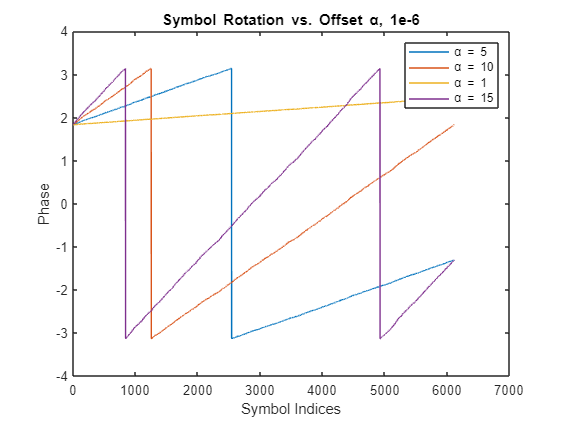

%plot phase as a function of n
ph_1 = angle(rot_symb1); ph_2 = angle(rot_symb2); ph_3 = angle(rot_symb3); ph_4 = angle(rot_symb4); 
x = 1:length(rot_symb1); 
plot(x, [ph_1, ph_2, ph_3, ph_4])
title('Symbol Rotation vs. Offset \alpha, 1e-6')
xlabel('Symbol Indices')
ylabel('Phase')
legend('\alpha = 5', '\alpha = 10', '\alpha = 1', '\alpha = 15')

## Q: what values of $\alpha$ does NN performance degrade? 

This section is dedicated to evaluating the bounds of the NN performance 

%training sets 
path = 'D:\Data\Doppler\Train Data\'; %external drive for storing data
cd(path)

M = 16; %mod order 
nb = 10004; %number of integers

packets = 100; 
window = 4; 

rng(0)

ratio = (1:15)*1e-6; %different rotation lengths 

for alpha = ratio
    msg = randi([0 sum(M)-1], nb, 1);
    symbols = dvbsapskmod(msg, M, 's2x'); 
    
    offset = (exp(-1i*2*pi*alpha*(0:length(symbols)-1)))';
    
    rxData = symbols.*offset; 
    
    train_data = makeInputMat(rxData,window);
    train_data = train_data(:,1:end-window);
    symbols = symbols(1+window:end);
    target = round([real(symbols) imag(symbols)],5)';

    x_train = zeros(size(train_data,1),size(train_data,2)*packets);
    y_train = zeros(size(target,1),size(target,2)*packets);
    
    %validation data
    msg = randi([0 sum(M)-1], nb, 1);
    symbols = dvbsapskmod(msg, M, 's2x');
    
    rxData = symbols.*offset; 
    
    val_data = makeInputMat(rxData,window);
    val_data = val_data(:,1:end-window);
    symbols = symbols(1+window:end);
    val_target = round([real(symbols) imag(symbols)],5)';
    
     %train data
        for iter = 1:packets
            x_train(:,((iter-1)*size(train_data,2)+1):(iter*size(train_data,2))) = train_data;
            y_train(:,((iter-1)*size(target,2)+1):(iter*size(target,2))) = target;
            if iter ~= packets
                msg = randi([0 sum(M)-1], nb, 1);
                symbols = dvbsapskmod(msg, M, 's2x');
               
                rxData = symbols.*offset; 
        
                train_data = makeInputMat(rxData,window);
                train_data = train_data(:,1:end-window);
                symbols = symbols(1+window:end);
                target = round([real(symbols) imag(symbols)],5)';
            end 
        end 

    x_train = x_train'; 
    y_train = y_train';
        
    val_data = val_data'; 
    val_target = val_target'; 

    app = alpha.*1e6;
    filename = sprintf('DVBS_dopp_ratio_%d', app); 

    save(filename, 'x_train', 'y_train', 'val_data', 'val_target'); 
end 

%test data
rng(0); 
M=16;
window = 4;
nb = 10004;

path = 'D:\Data\Doppler\Test Data';
cd(path); 

ratio = 15*1e-6; %different rotation lengths 

for alpha = ratio
    offset = (exp(-1i*2*pi*alpha*(0:nb-1)))';
    arr = 15;  
    mkdir(sprintf('ratio_%d', arr))
    cd(sprintf('ratio_%d', arr))

    for i = 1:10 
        msg = randi([0 sum(M)-1], nb, 1);
        symbols = dvbsapskmod(msg, M, 's2x');
        
        rxData = symbols.*offset; 
        
        train_data = makeInputMat(rxData,window);
        train_data = train_data(:,1:end-window);
        symbols = symbols(1+window:end);
        target = round([real(symbols) imag(symbols)],5)';
        
        train_data = train_data'; 
        
        filename_test = sprintf('DVBSAPSK_pred_ratio_%d_%d', [arr,i]); 
        save(filename_test, 'train_data', 'target'); 

    end
    cd(path)
end 